# Project 3 - Matlab - Covid-19 Pandemic

*Pablo Martínez, Oriol Bustos*

In this third and last project..

%addpath(['C:/Users/oriol/Escritorio/[4] Estudios/[1] EBM/[1.S8]/[4.1.2] DPVL/data_lab/Project 3/Pandemic/'])
%addpath(tudirectorio)

## 1. Density effect

d = linspace(0.01, 0.5, 4);
plot_epidemic_curves_check = false
for i=1:4
    result = Pandemic_Matlab_ex1(d(i), plot_epidemic_curves_check);
end
result

## 2. Create a movie

d = 0.01
plot_epidemic_curves_check = false
result = Pandemic_Matlab_ex2(d, plot_epidemic_curves_check);

movie(result.M)

## 3. The Rho number and Re-infections

Result = Pandemic_Matlab_ex3(Input, false);
infection_matrix = Result.infection_matrix;
% Finding the Rho number: 
Rho_vals = zeros(size(infection_matrix(1,:)));
Reinfections = zeros(size(infection_matrix(1,:)));
for i=1:length(infection_matrix(:,1))
    Rho_vals(1,i) = sum(infection_matrix(i,:));
    Reinfections(1,i) = sum(infection_matrix(:,i));
end
mean_val = mean(Rho_vals);
reinf_num = sum(Reinfections);
disp(mean_val);
disp(reinf_num);

## 4. Finding Regrothws

fcorrer para diferentes escenarios la curva de infectados y con findpeaks contar el numero de picos, si hay vairos hay regrowths

d = linspace(0.01, 0.5, 4);
confinement = [0, 1];
confined_pc_values = [50, 80];
combinations = [];

% generate combinations
for density = d
    for conf = confinement
        if conf == 0
            combinations = [combinations; density, 0, 1]; 
        else
            for confined_pc = confined_pc_values
                combinations = [combinations; density, 1, confined_pc];
            end
        end
    end
end
peakCounts = zeros(size(combinations, 1), 1);

for i = 1:size(combinations, 1)
    density = combinations(i, 1);
    conf = combinations(i, 2);
    confined_percent = combinations(i, 3);

    result = Pandemic_Matlab_ex4(density, false, conf, confined_percent);
    [peaks, ~] = findpeaks(result.infected);
    peakCounts(i) = numel(peaks);
end

disp('Combinations and their peak counts:');
for i = 1:size(combinations, 1)
    fprintf('Density: %.2f, Confinement: %d, Confined Percent: %d, Peaks: %d\n', ...
        combinations(i, 1), combinations(i, 2), combinations(i, 3), peakCounts(i));
end


Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------

## 5. Opening the Gaps

max_gap_value = 10;

Combinations and their peak counts:


max_iter_mean = 5;
gapsize = 1:max_gap_value


Density: 0.01, Confinement: 0, Confined Percent: 1, Peaks: 1
Density: 0.01, Confinement: 1, Confined Percent: 50, Peaks: 0
Density: 0.01, Confinement: 1, Confined Percent: 80, Peaks: 0
Density: 0.17, Confinement: 0, Confined Percent: 1, Peaks: 11
Density: 0.17, Confinement: 1, Confined Percent: 50, Peaks: 20
Density: 0.17, Confinement: 1, Confined Percent: 80, Peaks: 3
Density: 0.34, Confinement: 0, Confined Percent: 1, Peaks: 3
Density: 0.34, Confinement: 1, Confined Percent: 50, Peaks: 13
Density: 0.34, Confinement: 1, Confined Percent: 80, Peaks: 15
Density: 0.50, Confinement: 0, Confined Percent: 1, Peaks: 7
Density: 0.50, Confinement: 1, Confined Percent: 50, Peaks: 8
Density: 0.50, Confinement: 1, Confined Percent: 80, Peaks: 6


% Maximum number of iterations
max_iter = 1000;
% Size of the grid  (it's a square grid)
size_x = 100; % size_x x size_x is the size of the grid in poitns
% Density of population
density = 0.08;
% Number of people in the simulation
people = round((size_x)^2*density);
% Border parameters:
inner_border = 1; % 0 no inner border, 1 with inner border
gap = 7; % oberture in the imperfect border
% Health parameters:
sick_pc = 10; % percentage of sick people (all grid, or within inner border)
max_sick_time = 30; % time of recovery after being infected (in average)
% Movement parameters:
confinement = 0; % 0 no confinement, 1 confinment.
confined_pc = 50;% degree of confinement in percetage (people not moving)
% Plot parameters
do_plot = 0; % 0 plot the result, 1 don't plot it.


max_mat = zeros(max_iter_mean,max_gap_value);
for it_no = 1:max_iter_mean
    maxInfectedTime = zeros(1,max_gap_value);
    for ii = gapsize
        d = 0.05;
        people= round((size_x)^2*d);
        Input = struct('max_iter', max_iter, 'people', people,...,
            'size_x', size_x,...,
            'inner_border', 1,...,
            'gap', ii,...,
            'sick_pc', sick_pc,...,
            'max_sick_time', max_sick_time,...,
            'confinement', 0,...,
            'confined_pc',0.5,...,
            'do_plot', 0);
        Result = Covid19_Simulator(Input);
        infected = Result.infected;
        [max_inf,max_loc] = max(infected);
        maxInfectedTime(ii) = max_loc;
    end
    max_mat(it_no,:) = maxInfectedTime;
end


figure;
plot(gapsize, mean(maxInfectedTime,1),'-o');
xlabel('Gap'); ylabel('Time to Max Infected')

 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation


   200



x=1;
maxInfectedTime = zeros(10,1);
for mov = 0.01:0.1:1
    d = 0.1;
    people= round((size_x)^2*d);
    Input = struct('max_iter', max_iter, 'people', people,...,
        'size_x', size_x,...,
        'inner_border', 1,...,

   831   609   560



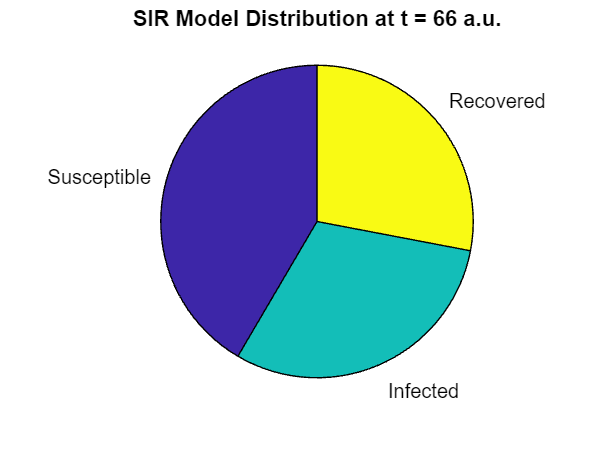

        'gap', 3,...,
        'sick_pc', sick_pc,...,
        'max_sick_time', max_sick_time,...,
        'confinement', 1,...,

        'confined_pc',mov,...,
        'do_plot', 0);
    Result = Covid19_Simulator(Input);
    infected = Result.infected;
    [inf,i] = max(infected);
    maxInfectedTime(x) = i;
    x = x+1;
end

figure;
mov = 0.01:0.1:1;
plot(mov, maxInfectedTime)

## 6. SIR Model

aaa

density = 0.2;

result = Pandemic_Matlab_ex6(density, false);
disp(length(result.non_infected))
time_index = floor(length(result.non_infected)/ 3);

S = result.non_infected(time_index);
I = result.infected(time_index);
R = result.recovered(time_index);

values = [S I R];
disp(values)
figure;
pie(values, {'Susceptible', 'Infected', 'Recovered'});
titlesss = sprintf('SIR Model Distribution at t = %g a.u.', time_index);
title(titlesss);

## 7. Surface Plot

aaa

## 8. Infection Probability

aaa

## 9. Extra Exercise (Optional)